# Distortion and noise

This live script proceeds after displacement_vector_field.mlx and includes combining the defined distortions and random topographic noise to the image. The performance of the Lawler-Fujita method is partially studied here. A more extensive examination will be included in a script file.

image_length = 128;
image_height = 128;
atom_diameter = 8;

lambda = 0.2;
lambda = lambda*2*pi/atom_diameter;

Q_x = [1 0];
Q_y = [-Q_x(2) Q_x(1)]; % just to ensure orthogonality
Q_x = Q_x * 2*pi / (norm(Q_x)*atom_diameter);
Q_y = Q_y * 2*pi / (norm(Q_y)*atom_diameter);

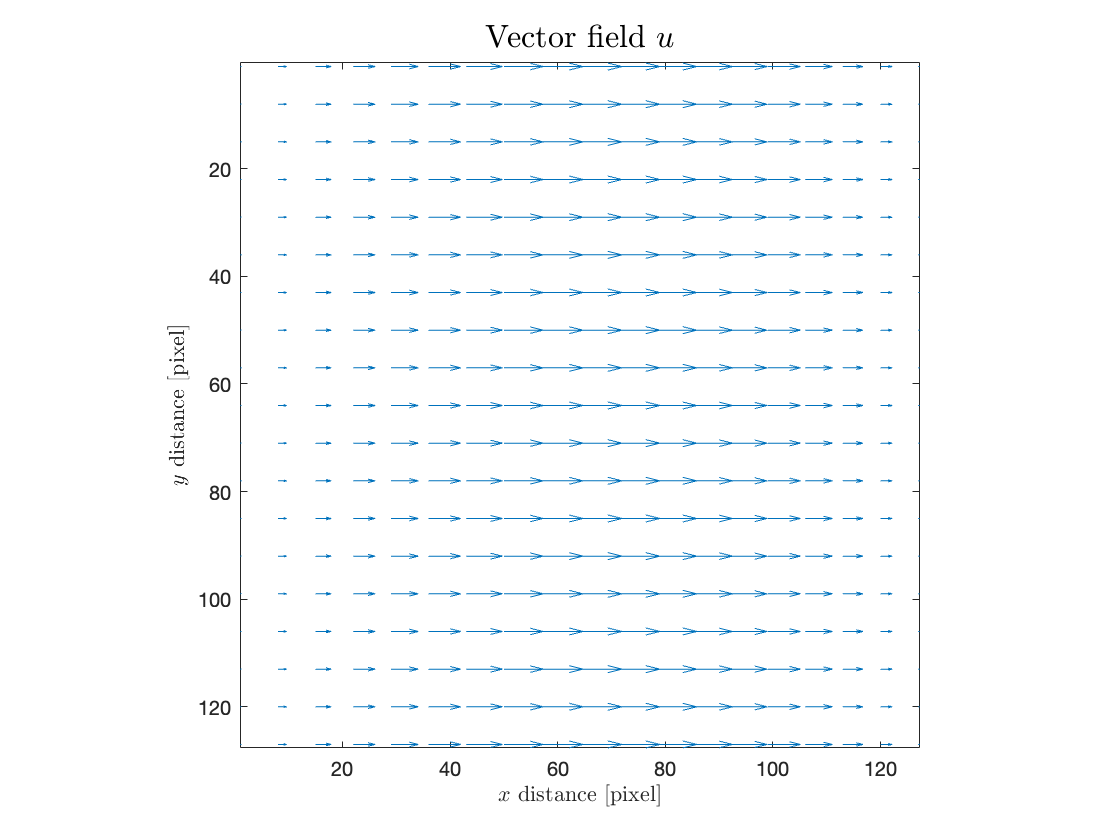

u = uCreate(image_height,image_length,atom_diameter,[0 0],[1 0],[0 0]);
uPlot(u,"$u$");

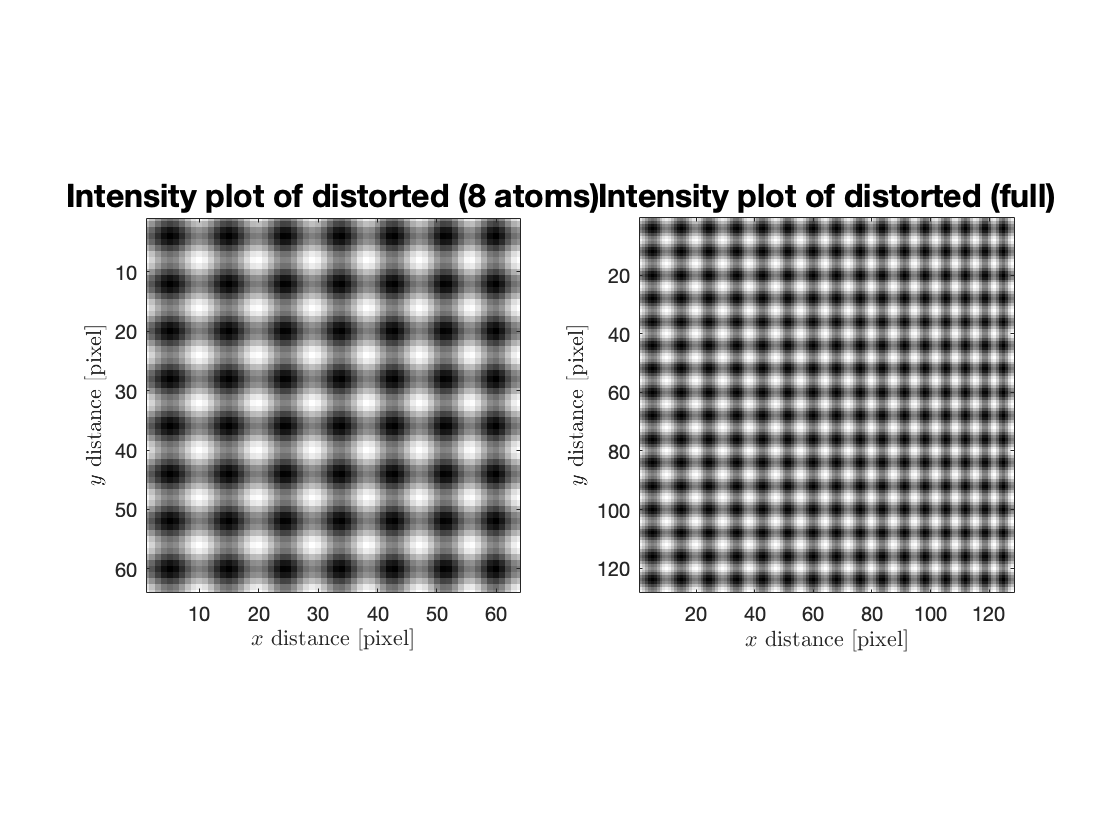


lattice = normies(uTransform(u,Q_x,Q_y))*atom_diameter/2;
comboPlot(lattice,"distorted",atom_diameter);

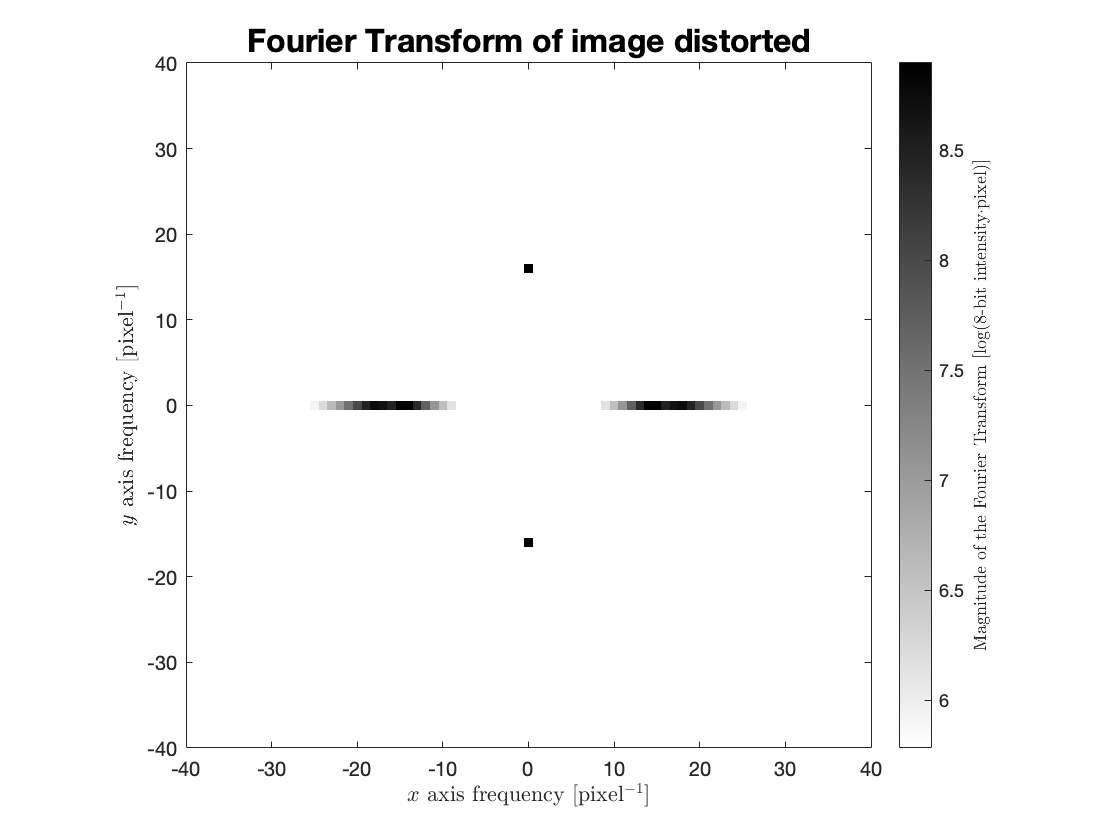

lattice_fft = myFFT(lattice,"distorted");

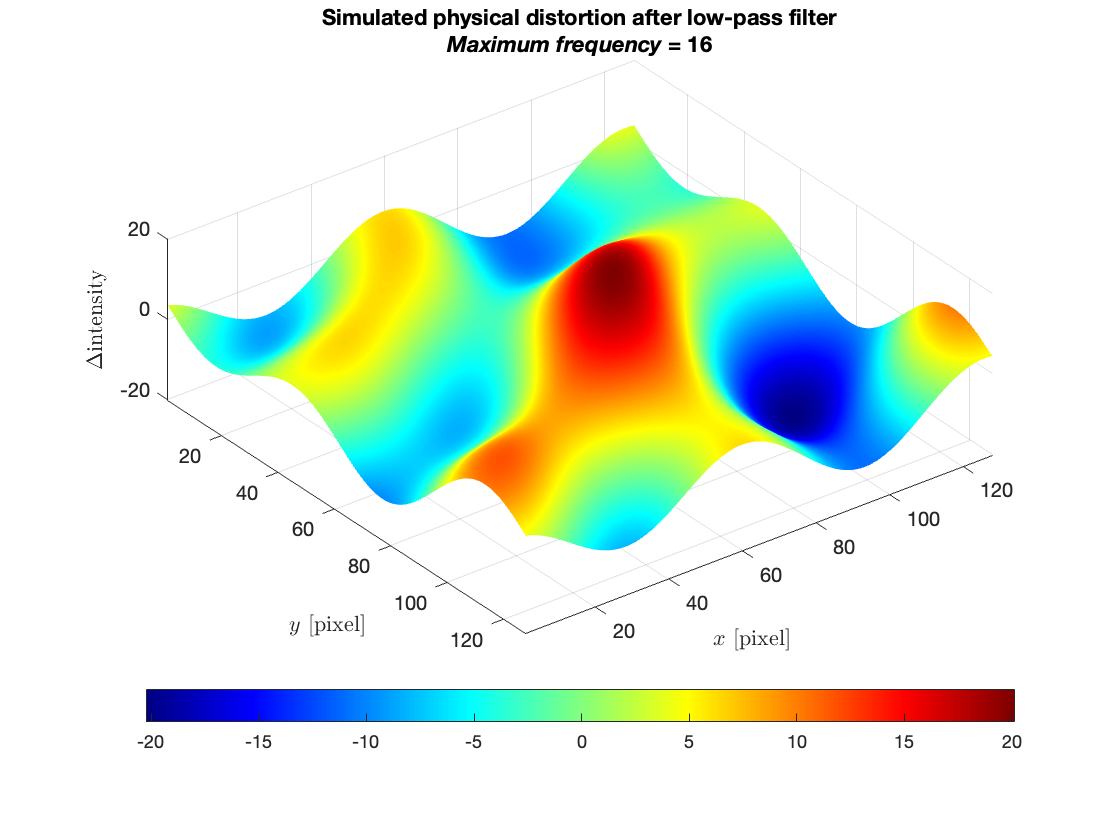


noise = noiseCreate(image_height,image_length,atom_diameter,10,1); % maxl, mag
noisePlot(image_height,image_length,noise,[],atom_diameter);

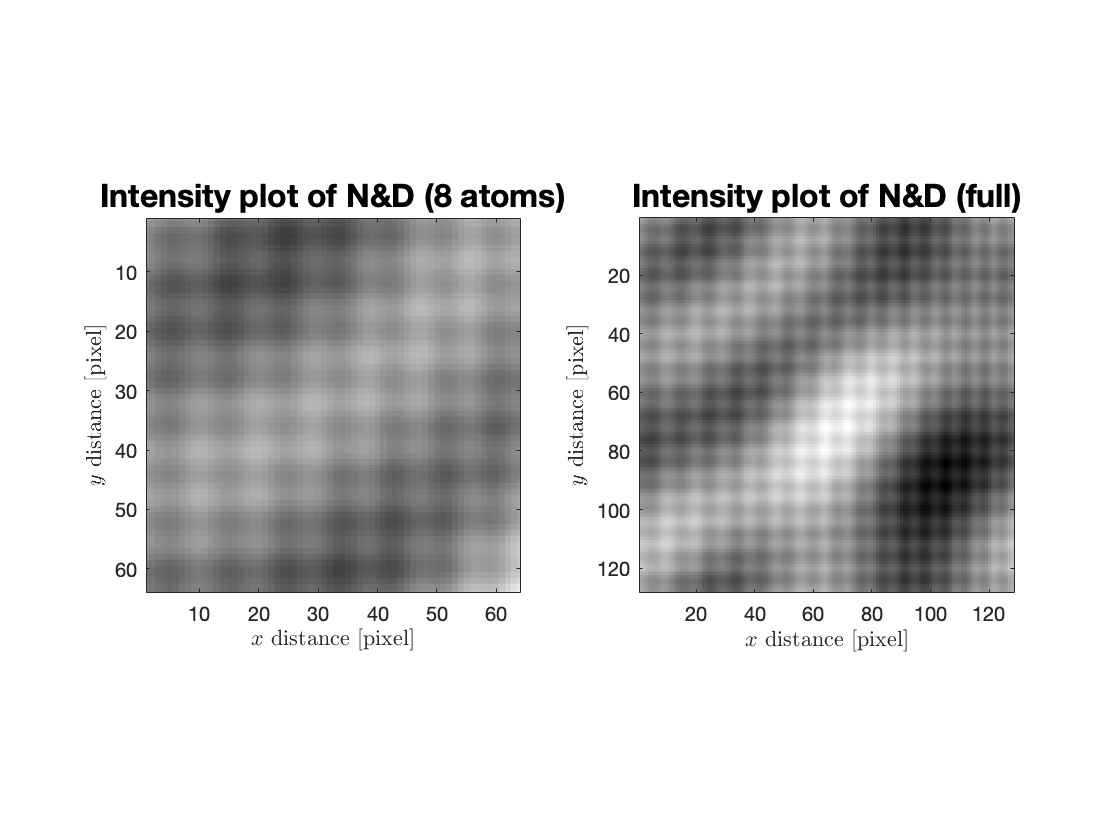


nlattice = lattice+noise;
comboPlot(nlattice,"N&D",atom_diameter);

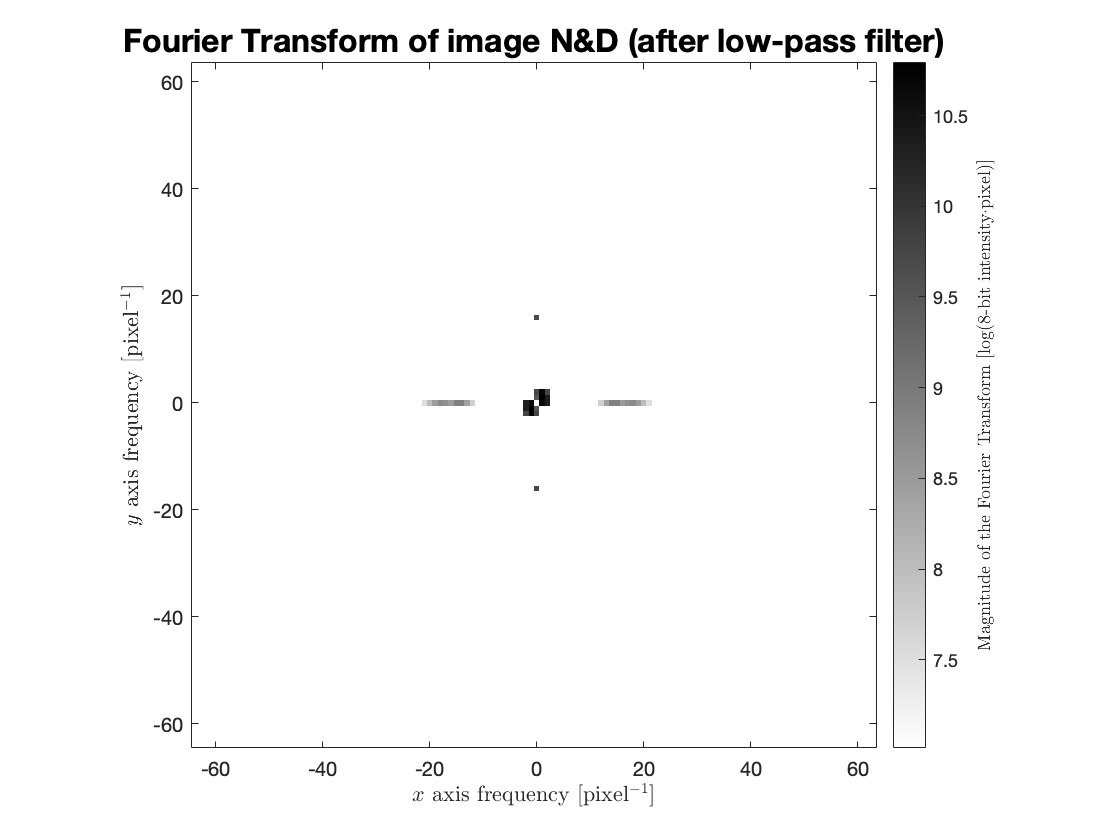

nlattice_fft = myFFT(nlattice,"N&D",[],atom_diameter/100); % just for full display

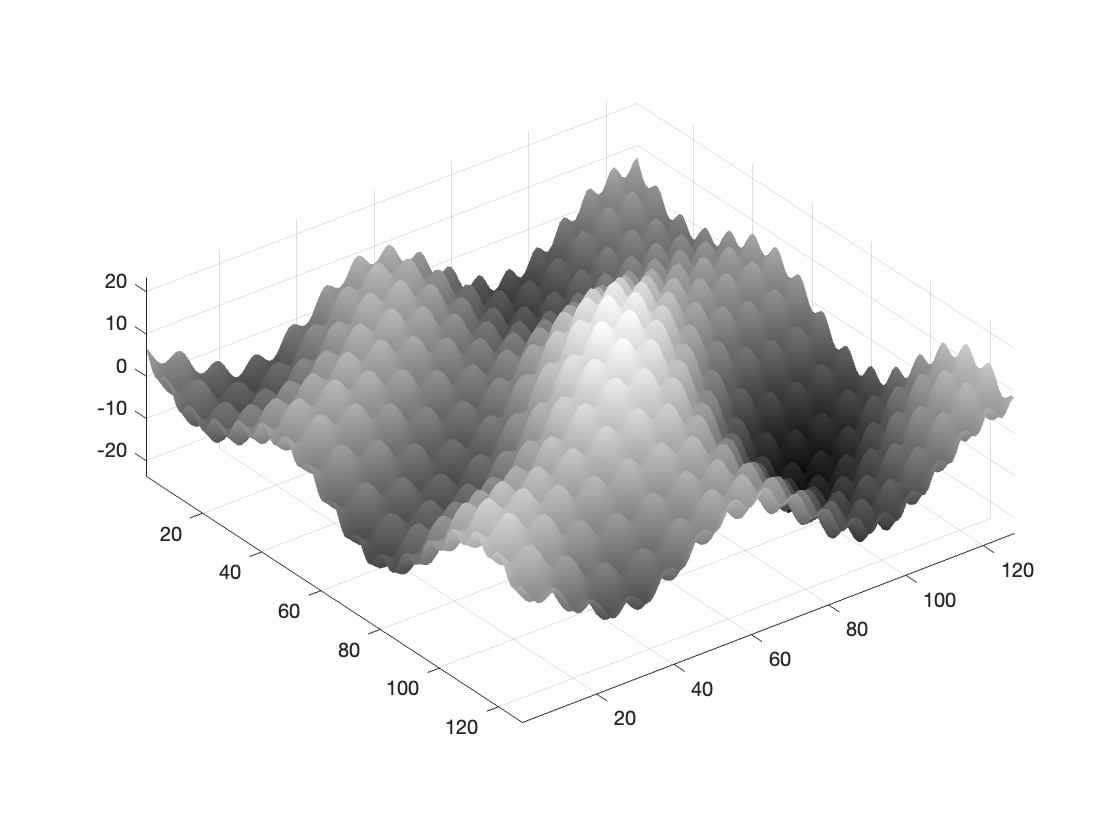


surf(nlattice);
shading interp;
axis equal;
set(gca,"YDir","reverse");
colormap(gray);

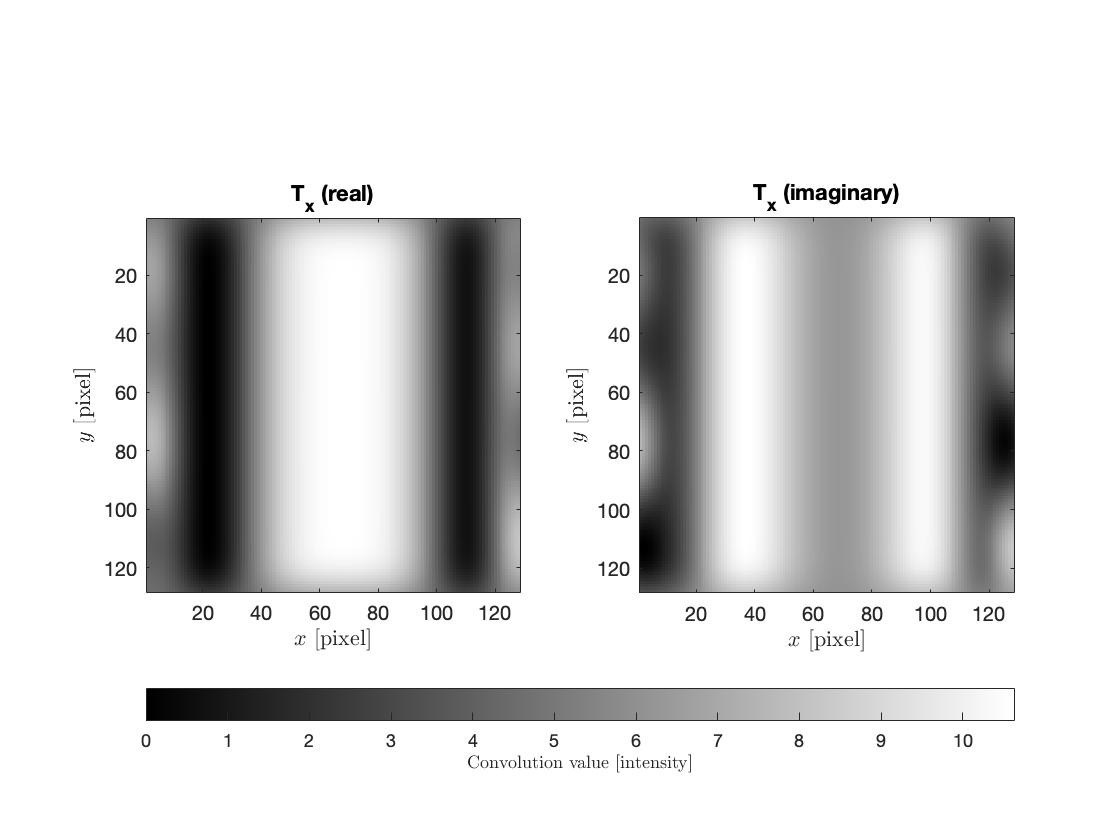

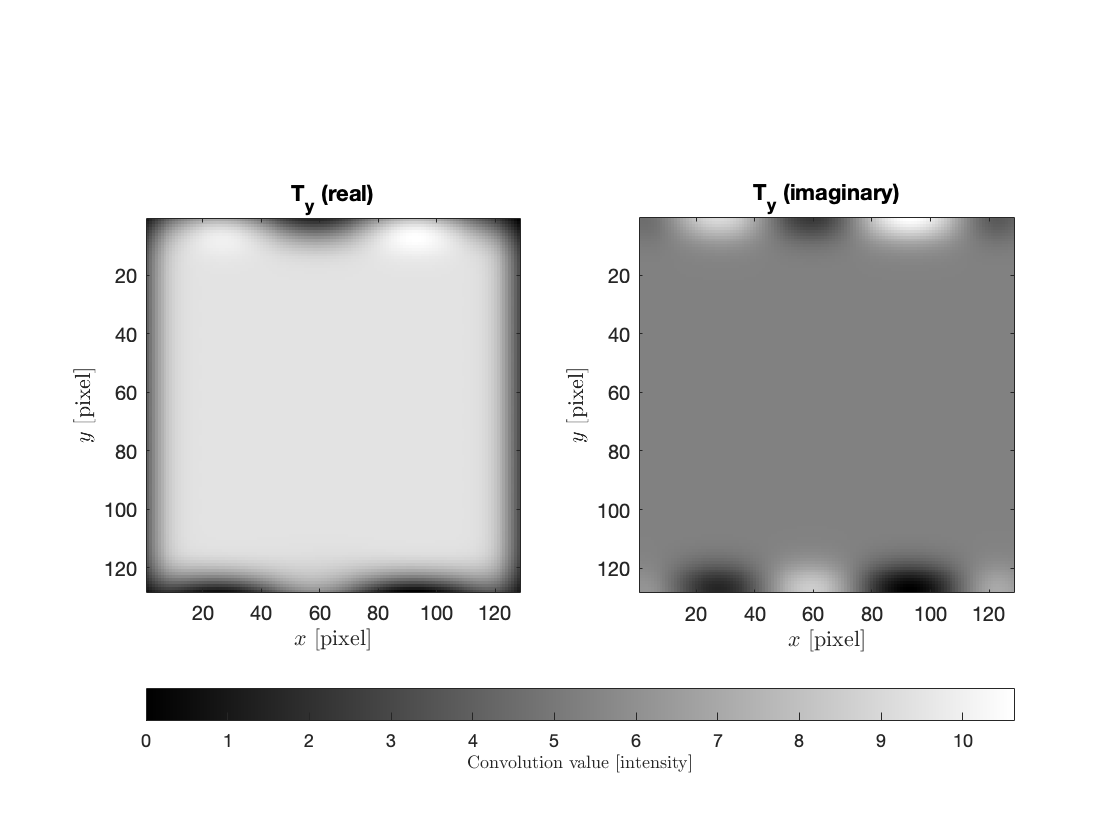

ucalc = myConv(nlattice,Q_x,Q_y,lambda);

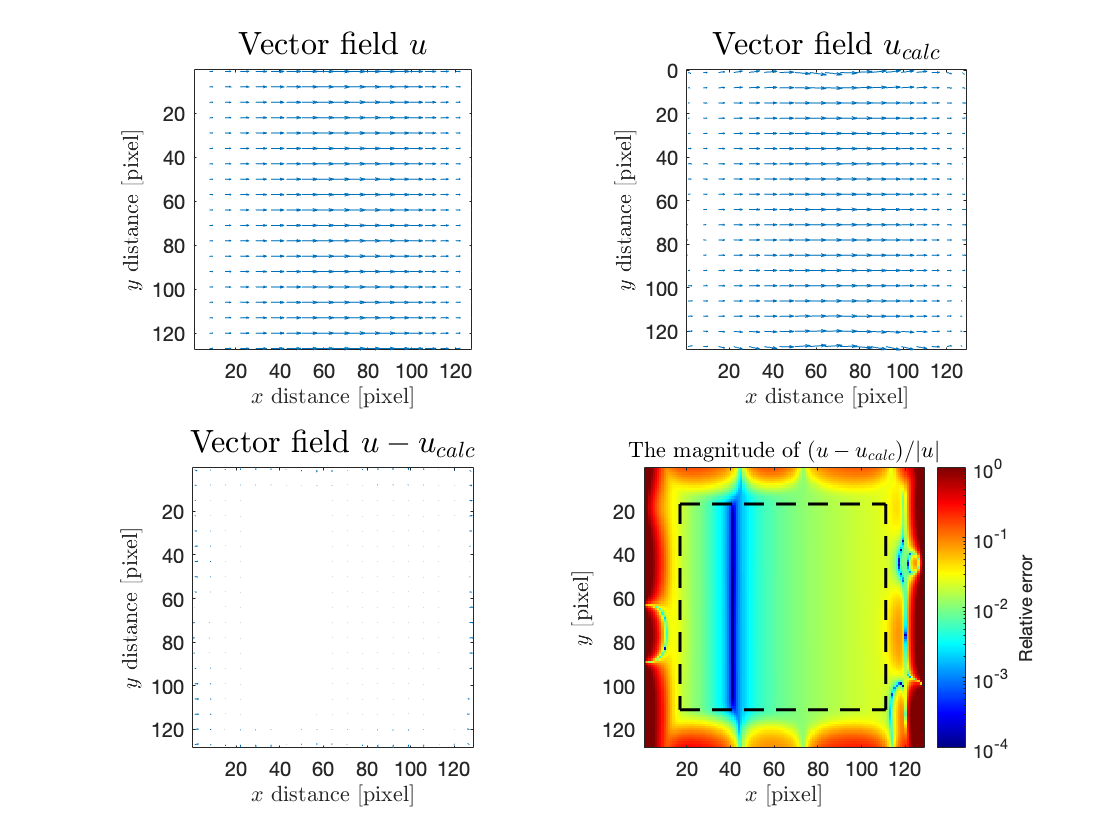

uComboPlot(u,ucalc,lambda);


if image_length-2*ceil(2.58/lambda)<=0 && image_height-2*ceil(2.58/lambda)<=0
    error("No pixels without padded zeros remain.");
else
    npixel = (image_length-2*ceil(2.58/lambda))*(image_height-2*ceil(2.58/lambda));
    % the number of pixels averaged
    disp("Number of pixels averaged: " + npixel + " (" + ...
        npixel/(image_length*image_height)*100 + "%)");
end

Number of pixels averaged: 8836 (53.9307%)



[meanErr, stdErr] = uCompare(u,ucalc,lambda);
disp("Error is: " + meanErr + "+/-" + stdErr*2.58 + " (99% confidence)");

Error is: 0.011399+/-0.018086 (99% confidence)


disp("Total error is: " + (meanErr+stdErr*2.58) + " (99% confidence)");

Total error is: 0.029485 (99% confidence)


disp("Errors are relative unless stated otherwise.");

Errors are relative unless stated otherwise.
